clearvars -except N;
close all;

cd '/MATLAB Drive/cs485/RF_code'
% addpaths
addpath('./internal');
addpath('./external');
addpath('./external/libsvm-3.18/matlab');
run('external/vlfeat-0.9.18/toolbox/vl_setup.m'); % vlfeat library

% conf.checkpoint = './Q#2_1205.mat';
conf.checkpoint = './1211_Q3.mat';%'./tmp_1210_Q2.mat';


if exist(conf.checkpoint)
  load(conf.checkpoint);
else
  disp('WARN: start from the scratch!')
end

## -  Experiment with Caltech dataset for image categorisation (Coursework 2)

**Q1. [5] ****K-means codebook**

We randomly select** 100k descriptors** for K-means clustering for building the visual vocabulary (due to memory issue). Open the main_guideline.m and select/load the dataset.

>> [data_train, data_test] = getData('Caltech'); % Select dataset

Set 'showImg = 0' in getData.m if you want to stop displaying training and testing images. Complete getData.m by writing your own lines of code to **obtain the visual vocabulary and the bag-of-words histograms for both training and testing data**. You can use any existing code for Kmeans (note different codes require different memory and computation time). Show, measure and discuss the followings:

• vocabulary size,

• bag-of-words histograms of example training/testing images,

• vector quantisation process  

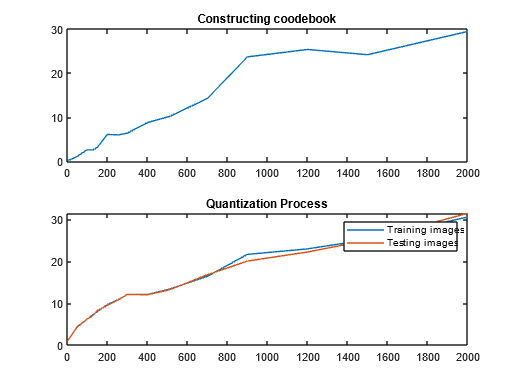

figure
subplot(2,1,1)
plot(n_w, t_k) % 
title('Constructing coodebook') % converges after 300
subplot(2,1,2)
plot(n_w, t_q_tr, n_w, t_q_te)
title('Quantization Process')
legend('Training images', 'Testing images') % linearly inscreasing

### Q#1. Visualize results

- time spent depending on # of vocab size

- examples of bag-of-words histogram w/ training and testing images

- vector quantisation process <--- do we need this? or just description

#### 1. time spent - need fancier one?

acc = accuracies*100

acc =    22.6667   44.0000   50.6667   59.3333   62.6667   66.6667   66.6667   68.0000   67.3333   68.0000   67.3333   70.0000   66.6667   69.3333   64.0000   64.6667   64.0000   68.0000


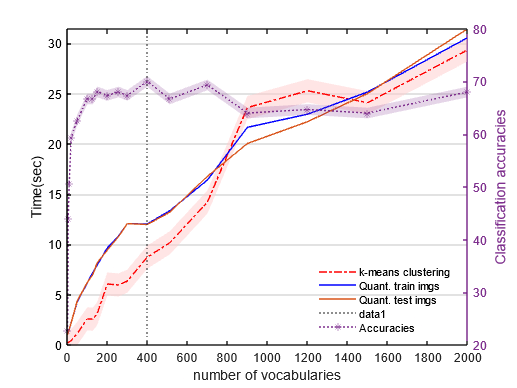


figure 
xconf = [n_w n_w(end:-1:1)] ;         
yconf = [t_k+1.15 t_k(end:-1:1)-1.15];

p = fill(xconf, yconf,'red');
p.FaceColor = [1 0.8 0.8];
p.FaceAlpha = 0.5;
p.EdgeColor = 'none';
hold on

plot(n_w, t_k, '-.r')
plot(n_w, t_q_tr, 'b', n_w, t_q_te)
set(gca,"XGrid","off","YGrid","on")
ylim([0 inf]) %  tight
xlabel('number of vocabularies')
ylabel('Time(sec)')
yyaxis right
plot(n_w, acc, ':*')
aconf = [acc+1.01 acc(end:-1:1)-1.01];
ylabel('Classification accuracies(%)')
q = fill(xconf, aconf,'black');
q.FaceColor = [0.4940 0.1840 0.5560];%[0.9 0.9 0.9];
q.FaceAlpha = 0.2;
q.EdgeColor = 'none';

legend({'','k-means clustering', 'Quant. train imgs', 'Quant. test imgs', 'Accuracies'}, 'Location','southeast') % linearly inscreasing
legend('boxoff')
hold off

ax = gca;
% chart = ax.Children(1);
% datatip(chart,8,0.46);
xline(ax, 400, ':')

- constructing codebook by k-means clustering looks logarithmatically time-consuming depending on the number of vocabulary

- time spent for quantization process shows lineary increasing by the number of vocabulary.

- it is hard to make a decision for adequate vocabulary size but we pick the # of 400 vocabulary size considering the classifiation accuracy of the classifier in Q#2.

  Test perform with  **vocab size = 400 **for Q#2

#### 2. examples of bag-of-words - USE THIS EXAMPLE ( vocab = 100)

rows = 5 %randi([1,  size(desc_tr, 1)], 1, 1)

rows = 5

cols = 12 %randi([1,  size(desc_tr, 2)], 1, 1)

cols = 12

n = 6; nw = n_w(n)

nw = 100

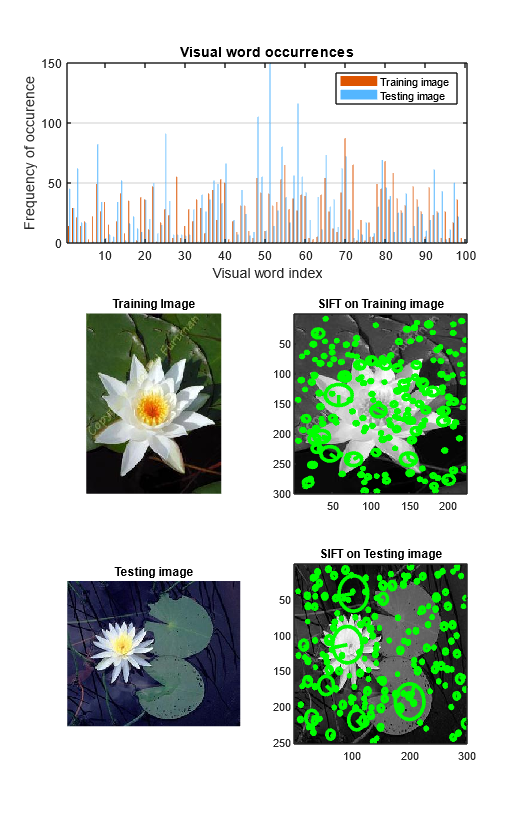

d_tr = cell2mat(BoWs_trs(1,n));
d_te = cell2mat(BoWs_tes(1,n));

% Create the histogram using the histogram function
figure
subplot (3,1,1)
% h1 = histogram(reshape(BoWs_tr(rows, cols, :), 1, n));
% h1.EdgeAlpha = 0;
% h1.BinWidth = 0.75;
% hold on
% h2 = histogram(reshape(BoWs_te(rows, cols, :), 1, n), h1.BinEdges);
% h2.EdgeAlpha = 0;
% h2.BinWidth = 0.75;
bar([reshape(d_tr(rows, cols, :), 1, nw);  reshape(d_te(rows, cols, :), 1, nw) ]', 'EdgeColor', 'none','LineWidth', 2.5)
colororder("reef")
set(gca,"XGrid","off","YGrid","on")
hold off
% Add a legend
legend('Training image', 'Testing image')
% Add title and axis labels
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurence')
pos = get(gcf, 'Position');
set(gcf, 'Position',pos+[0 -500 0 500])
subplot (3,2,3)
imshow(tr_img{rows,cols})
title('Training Image')
subplot (3,2,4)
im = im2single(rgb2gray(tr_img{5,12}));
[f, d] = vl_sift(im);
imagesc(im) ; colormap gray; hold on ;
vl_plotframe(f) ;
title('SIFT on Training image')
subplot(3,2,5)
imshow(te_img{rows,cols})
title('Testing image')
subplot(3,2,6)
im = im2single(rgb2gray(te_img{5,12}));
[f, d] = vl_sift(im);
imagesc(im) ; colormap gray; hold on ;
vl_plotframe(f) ;
title('SIFT on Testing image')

- **vector quantization process**

SIFT for descriptor extraction -> randomly select 100k descriptor -> k-means clustering for centroids -> assign to desriptor -> count to build histogram.

**Q2. [10] RF classifier**

Train and test Random Forest using the training and testing data set in the form of bag-of-words obtained in **Q1**. Change the RF parameters (including the number of trees, the depth of trees, the degree of randomness parameter, the type of weak-learners: e.g. axis-aligned or two-pixel test), and show and discuss the results:

• recognition accuracy, confusion matrix, <- best one

• example success/failures, <- examples

• time-efficiency of training/testing, 

 -> comparison by

  1) num # of **Trees => 1000**

  2) max num # of tree **DEPTH=> 9**

  3) num # of **splits**(randomness**)=>4**

• impact of the vocabulary size on classification accuracy.  

  4) type of weak learnes=> axis-algined(small vocab size), 2-pixel test(large vocab size)

- time-efficiency of training/testing

1) by the **number of trees **( axis-aligned, n=12, k = 400, depth=5, split=5)

n=12;
d_tr = cell2mat(BoWs_trs(1,n));
d_te = cell2mat(BoWs_tes(1,n));
data_train = flatten_add_labels(d_tr);
data_test = flatten_add_labels(d_te);
% param.num = 10;    % Number of trees
param.depth = 5;    % trees depth
param.splitNum = 5  ; % Number of trials in split function
param.split = 'IG'; % Currently support 'information gain' only

t_tr_by_t =  [];
t_te_by_t = [];
acc_by_t = [];
num_tree = [5 10 50 100 200 400 600 800 1000 1500 2000]
for t=1:length(num_tree)
    param.num = num_tree(t);
    [t_tr, t_te, acc] = RF_classifier(data_train, data_test, param, 0);
    t_tr_by_t = cat(2, t_tr_by_t, t_tr);
    t_te_by_t = cat(2, t_te_by_t, t_te);
    acc_by_t = cat(2, acc_by_t, acc);
end

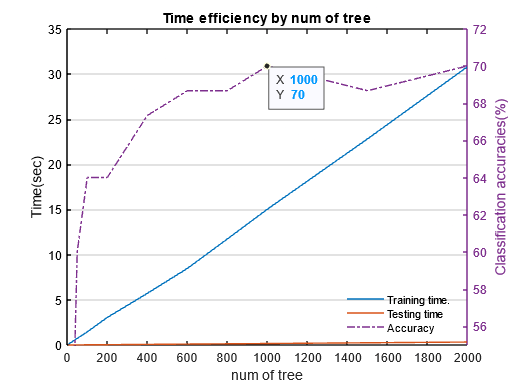

acc = acc_by_t * 100; 
figure
plot(num_tree, t_tr_by_t, num_tree, t_te_by_t);
xlabel('num of tree')
ylabel('Time(sec)') 

title('') 
yyaxis right
ax = gca;
ax.YColor = '[0.4940 0.1840 0.5560]';

hold on
plot(num_tree, acc, '-.', "Color", "[0.4940 0.1840 0.5560]");
hold off
ylim([55 72])
xlabel('num of tree')
ylabel('Classification accuracies(%)') 
legend({'Training time.', 'Testing time', 'Accuracy'}, 'Location','southeast')
legend('boxoff') 
title('Time efficiency by num of tree')
% xline(ax, [9 12], ':');
set(gca,"XGrid","off","YGrid","on")



- time-complexity by tree **DEPTH** ( axis-aligned, n=12, k = 400)

n=12;
d_tr = cell2mat(BoWs_trs(1,n));
d_te = cell2mat(BoWs_tes(1,n));
data_train = flatten_add_labels(d_tr);
data_test = flatten_add_labels(d_te);
param.num = 3;    % Number of trees
% param.depth = 7;    % trees depth
param.splitNum = 3  ; % Number of trials in split function
param.split = 'IG'; % Currently support 'information gain' only

t_tr_by_d =  [];
t_te_by_d = [];
acc_by_d = [];
depth_range= 2:22;
for d=1: length(depth_range)
    param.depth = depth_range(d);
    [t_tr, t_te, acc] = RF_classifier(data_train, data_test, param, 0);
    t_tr_by_d = cat(2, t_tr_by_d, t_tr);
    t_te_by_d = cat(2, t_te_by_d, t_te);
    acc_by_d = cat(2, acc_by_d, acc);
end

% newcolors = [0.83 0.14 0.14
%              1.00 0.54 0.00
%              0.47 0.25 0.80
%              0.25 0.80 0.54];
% 
% colororder(newcolors)
acc = acc_by_d * 100;
d_x = depth_range(:,1:end-1);;
figure
plot(d_x, t_tr_by_d, d_x, t_te_by_d);

Accuracy =   Line (Accuracy) - 속성 있음:

              Color: [0.4940 0.1840 0.5560]
          LineStyle: '-.'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21]
              YData: [20.6667 20.6667 24.6667 22 30.6667 31.3333 28.6667 36.6667 28.0000 33.3333 36 28.6667 24.6667 28.0000 26.6667 31.3333 29.3333 38.6667 34 28.6667]

  모든 속성 표시


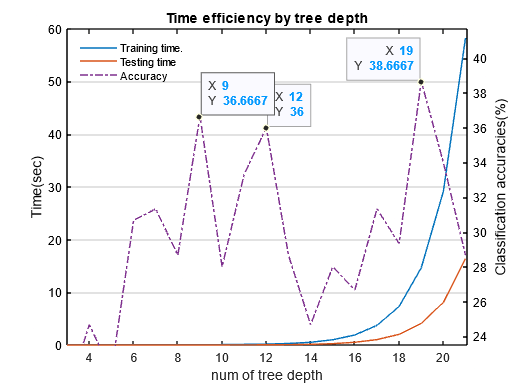

xlabel('num of tree depth')
ylabel('Time(sec)') 


yyaxis right
ax = gca;
ax.YColor = 'k';
hold on
plot(d_x, acc, '-.', "Color", "[0.4940 0.1840 0.5560]");
hold off
% ylim([55 70])
xlabel('num of tree depth')
ylabel('Classification accuracies(%)') 
legend({'Training time.', 'Testing time', 'Accuracy'}, 'Location','northwest')
legend('boxoff') 
title('Time efficiency by tree depth')
% xline(ax, [9 12], ':');
set(gca,"XGrid","off","YGrid","on")

xlim([3.0 21.1])
yyaxis right
ylim([23.5 41.7])
yyaxis left
ylim([0.0 60.0])
 
yyaxis right
Accuracy = findobj(gcf, "DisplayName", "Accuracy")
datatip(Accuracy,12,36);
datatip(Accuracy,19,38.67);
datatip(Accuracy,9,36.67);


- time-complexity by degree of randomness ( axis-aligned, n=12, k = 400)

n=12;
d_tr = cell2mat(BoWs_trs(1,n));
d_te = cell2mat(BoWs_tes(1,n));
data_train = flatten_add_labels(d_tr);
data_test = flatten_add_labels(d_te);
param.num = 3;    % Number of trees
param.depth = 5;    % trees depth
% param.splitNum = 3  ; % Number of trials in split function
param.split = 'IG'; % Currently support 'information gain' only

t_tr_by_s =  [];
t_te_by_s = [];
acc_by_s = [];
n_splits = 1:10;
for d=1: length(n_splits)
    param.splitNum = n_splits(d);
    [t_tr, t_te, acc] = RF_classifier(data_train, data_test, param, 0);
    t_tr_by_s = cat(2, t_tr_by_s, t_tr);
    t_te_by_s = cat(2, t_te_by_s, t_te);
    acc_by_s = cat(2, acc_by_s, acc);
end

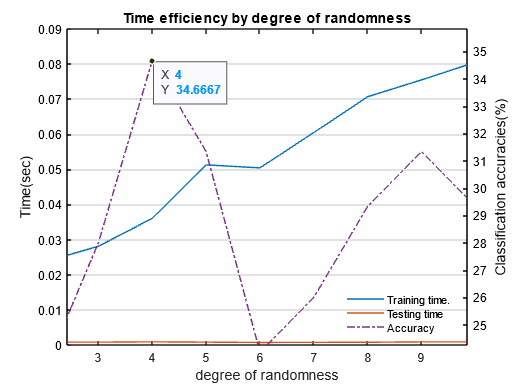

acc = acc_by_s * 100; 

figure
plot(n_splits, t_tr_by_s, n_splits, t_te_by_s);
xlabel('degree of randomness')
ylabel('Time(sec)') 

yyaxis right
ax = gca;
ax.YColor = 'k';
hold on
plot(n_splits, acc, '-.', "Color", "[0.4940 0.1840 0.5560]");
hold off
% ylim([55 70])
% xlabel('num of splits')
ylabel('Classification accuracies(%)') 
legend({'Training time.', 'Testing time', 'Accuracy'}, 'Location','southeast')
legend('boxoff') 
title('Time efficiency by degree of randomness')
% xline(ax, [9 12], ':');
set(gca,"XGrid","off","YGrid","on")

yyaxis right
Accuracy2 = findobj(gcf, "DisplayName", "Accuracy2")
datatip(Accuracy2,4,34.67);


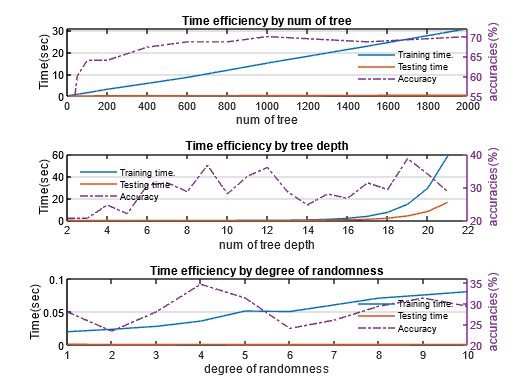

figure
tiledlayout("vertical")

nexttile  %% num tree

acc = acc_by_t * 100; 
plot(num_tree, t_tr_by_t, num_tree, t_te_by_t);
xlabel('num of tree')
ylabel('Time(sec)') 

title('') 
yyaxis right
ax = gca;
ax.YColor = '[0.4940 0.1840 0.5560]';
hold on
plot(num_tree, acc, '-.', "Color", "[0.4940 0.1840 0.5560]");
hold off
ylim([55 72])
xlabel('num of tree')
ylabel('accuracies(%)') 
legend({'Training time.', 'Testing time', 'Accuracy'}, 'Location','southeast')
legend('boxoff') 
title('Time efficiency by num of tree')
% xline(ax, [9 12], ':');
set(gca,"XGrid","off","YGrid","on")


nexttile %% tree depth

acc = acc_by_d * 100;
d_x = depth_range(:,1:end-1);
plot(d_x, t_tr_by_d, d_x, t_te_by_d);
xlabel('num of tree depth')
ylabel('Time(sec)') 

yyaxis right
ax = gca;
ax.YColor =  '[0.4940 0.1840 0.5560]';
hold on
plot(d_x, acc, '-.', "Color", "[0.4940 0.1840 0.5560]");
hold off
% ylim([55 70])
xlabel('num of tree depth')
ylabel('accuracies(%)') 
legend({'Training time.', 'Testing time', 'Accuracy'}, 'Location','northwest')
legend('boxoff') 
title('Time efficiency by tree depth')
% xline(ax, [9 12], ':');

set(gca,"XGrid","off","YGrid","on")
 
nexttile %% degree of randomness
acc = acc_by_s * 100; 
plot(n_splits, t_tr_by_s, n_splits, t_te_by_s);
xlabel('degree of randomness')
ylabel('Time(sec)') 

yyaxis right
ax = gca;
ax.YColor =  '[0.4940 0.1840 0.5560]';
hold on
plot(n_splits, acc, '-.', "Color", "[0.4940 0.1840 0.5560]");
hold off
% ylim([55 70])
% xlabel('num of splits')
ylabel('accuracies(%)') 
legend({'Training time.', 'Testing time', 'Accuracy'}, 'Location','southeast')
legend('boxoff') 
title('Time efficiency by degree of randomness')
% xline(ax, [9 12], ':');
set(gca,"XGrid","off","YGrid","on")

**4)-time efficiency comparision** axis-aligned Versus two-pixels test

   + impact of **vocab size vs accuracies on classification accuracy**

t_grow_trees =  [];
t_test_trees = [];
accuracies = [];

% fix param
param.num = 300;     % number of trees
param.depth = 6;    % trees depth
param.splitNum = 8; % Number of trials in split function
param.split = 'IG'; % Currently support 'information gain' only

for n=1:length(n_w)
    d_tr = cell2mat(BoWs_trs(1,n));
    d_te = cell2mat(BoWs_tes(1,n));
    data_train = flatten_add_labels(d_tr);
    data_test = flatten_add_labels(d_te);
    tic;
    trees = growTrees(data_train, param);
    t_tr = toc;
    t_grow_trees = cat(2, t_grow_trees, t_tr);
    tic
    testTrees_script;
    t_tec = toc;
    t_test_trees = cat(2, t_test_trees, t_tec);
    accuracies = cat(2, accuracies, accuracy_rf);
end

max(accuracies), find(accuracies==max(accuracies)), n_w(find(accuracies==max(accuracies)))

- comparison by **type of weak-learners**

**+  **impact of vocabulary size on classifcation accuracy

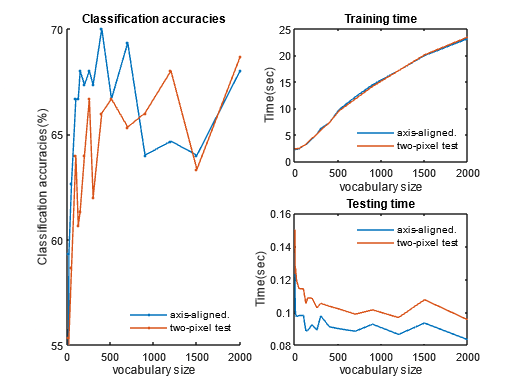

acc = accuracies * 100;
acc2 = accuracies_2px * 100;
figure
subplot(2,2,[1 3]);

hold on
plot(n_w, acc, n_w, acc2, "Marker", ".")
hold off
ylim([55 70])
xlabel('vocabulary size')
ylabel('Classification accuracies(%)') 
legend({'axis-aligned.', 'two-pixel test'}, 'Location','southeast')
legend('boxoff')
title('Classification accuracies')

subplot(2,2,2);
plot(n_w, t_grow_trees(:, 1:18), n_w, t_grow_trees(:, 19:end));
xlabel('vocabulary size')
ylabel('Time(sec)') 
legend({'axis-aligned.', 'two-pixel test'}, 'Location','southeast')
legend('boxoff')
title('Training time')
% 
subplot(2,2,4);
plot(n_w, t_test_trees(:, 1:18), n_w, t_test_trees(:, 19:end));
xlabel('vocabulary size')
ylabel('Time(sec)') 
legend({'axis-aligned.', 'two-pixel test'}, 'Location','northeast')
legend('boxoff')
title('Testing time')
legend('boxoff')

- **Random Forest Classifier  - comparision axis-aligned test Versus two-pixels test**

% flatten array and add labels
data_train = flatten_add_labels(d_tr); % 10x15x2000 -> 150x2000 + 1(label)
data_test = flatten_add_labels(d_te);

Training Random Forest... tree(300) depth(6) splits(8)


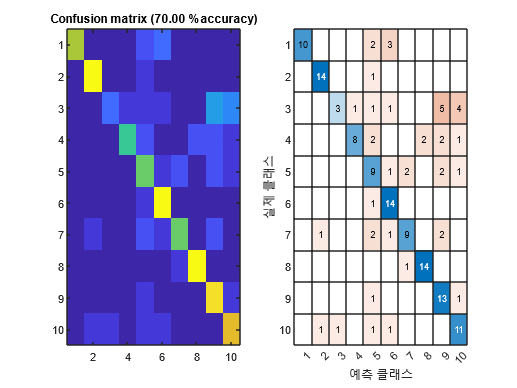

param.num = 300;     % number of trees

param.depth = 6;    % trees depth
param.splitNum = 8; % Number of trials in split function

t_tr = 7.8144

t_te = 0.1060

acc = 0.7000

param.split = 'IG'; % Currently support 'information gain' only

t_tr = 12.3663

t_te = 0.0953

acc = 0.6533

param.num = 300;    % Number of trees
param.depth = 6;    % trees depth
param.splitNum = 8  ; % Number of trials in split function
param.split = 'IG'; % Currently support 'information gain' only

n=12; %14;
d_tr = cell2mat(BoWs_trs(1,n));
d_te = cell2mat(BoWs_tes(1,n));
data_train = flatten_add_labels(d_tr);
data_test = flatten_add_labels(d_te);

Training Random Forest...
Training tree: 1
Training tree: 2
Training tree: 3
Training tree: 4
Training tree: 5
Training tree: 6
Training tree: 7
Training tree: 8
Training tree: 9
Training tree: 10
Training tree: 11
Training tree: 12
Training tree: 13
Training tree: 14
Training tree: 15
Training tree: 16
Training tree: 17
Training tree: 18
Training tree: 19
Training tree: 20
Training tree: 21
Training tree: 22
Training tree: 23
Training tree: 24
Training tree: 25
Training tree: 26
Training tree: 27
Training tree: 28
Training tree: 29
Training tree: 30
Training tree: 31
Training tree: 32
Training tree: 33
Training tree: 34
Training tree: 35
Training tree: 36
Training tree: 37
Training tree: 38
Training tree: 39
Training tree: 40
Training tree: 41
Training tree: 42
Training tree: 43
Training tree: 44
Training tree: 45
Training tree: 46
Training tree: 47
Training tree: 48
Training tree: 49
Training tree: 50
Training tree: 51
Training tree: 52
Training tree: 53
Training tree: 54
Training tr

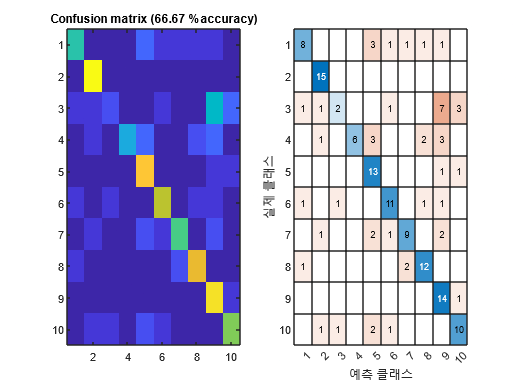

[t_tr, t_te, acc] = RF_classifier(data_train, data_test, param, 1);

t_tr, t_te, acc % k-means(400) + axis-aligned RF classifier 

t_tr_2px = 8.3362

t_te_2px = 0.1440

acc_2px = 0.6400

t_tr, t_te, acc % k-means(700) + axis-aligned RF classifier 

t_tr_2px = 12.5716

t_te_2px = 0.1081

acc_2px = 0.6933

param.num = 300;    % Number of trees
param.depth = 6;    % trees depth
param.splitNum = 8  ; % Number of trials in split function
param.split = 'IG'; % Currently support 'information gain' only

n=14; %700
d_tr = cell2mat(BoWs_trs(1,n));
d_te = cell2mat(BoWs_tes(1,n));
data_train = flatten_add_labels(d_tr);
data_test = flatten_add_labels(d_te);


Training Random Forest... tree(300) depth(6) splits(8)


[t_tr_2px, t_te_2px, acc_2px] = RF_classifier_2px(data_train, data_test, param, 1);

ans = 25.2959

ans = 22.9662

ans = 22.2189

t_tr_ax = 17.8518

t_te_ax = 0.1017

acc_ax = 0.6533

t_tr_2px, t_te_2px, acc_2px   % w/ k=400

t_tr_2px, t_te_2px, acc_2px   % w/ k=700

**Q3. [15] ****RF codebook**

In **Q1**, replace the K-means with the** random forest codebook**, i.e. applying RF to 128 dimensional descriptor vectors with their image category labels, and using the RF leaves as the visual vocabulary. With the bag-of-words representations of images obtained by the RF codebook, train and test Random Forest classifier similar to **Q2**. Try different parameters of the RF codebook and RF classifier, and show/discuss the results in comparison with the results of **Q2**, including the **vector quantisation complexity.**

Use the above Caltech101 dataset, i.e. 10 classes, 15 images per class for training, and 15 other images per class for testing. The examples are colour images of object categories, each with varying size of pixels. Preprocess* the data so training CNNs becomes easier. (*size-normalise and or zero-center image pixel values).  

% RF coding vs K-means coding in terms of Classification accuracy,
% training& testing time, and BoW time
% hyper paremters?
% as per RF codebook, vocabulary size K is not directrly controlled but
% upper bound is like this : K <= num_tree x 2^(max_depth-1) 6 x 2 ^9-1 = 

- K-means clustering codebook( K=1200                     + RF classifier(300, 6, 8) + (axis-algined or two-pixel test) 

 vs Random Forest Classifier ( 5 tree, 9 depth, 4 splits, + RF classifier(300, 6, 8) + (axis-algined or two-pixel test)

**for Q#3,**

- K-means(k=1200, n=16), axis-aligned, RF classfier(300, 6,8)

param.num = 300;    % Number of trees
param.depth = 6;    % trees depth
param.splitNum = 8  ; % Number of trials in split function

Training Random Forest...
Training tree: 1
Training tree: 2
Training tree: 3
Training tree: 4
Training tree: 5
Training tree: 6
Training tree: 7
Training tree: 8
Training tree: 9
Training tree: 10
Training tree: 11
Training tree: 12
Training tree: 13
Training tree: 14
Training tree: 15
Training tree: 16
Training tree: 17
Training tree: 18
Training tree: 19
Training tree: 20
Training tree: 21
Training tree: 22
Training tree: 23
Training tree: 24
Training tree: 25
Training tree: 26
Training tree: 27
Training tree: 28
Training tree: 29
Training tree: 30
Training tree: 31
Training tree: 32
Training tree: 33
Training tree: 34
Training tree: 35
Training tree: 36
Training tree: 37
Training tree: 38
Training tree: 39
Training tree: 40
Training tree: 41
Training tree: 42
Training tree: 43
Training tree: 44
Training tree: 45
Training tree: 46
Training tree: 47
Training tree: 48
Training tree: 49
Training tree: 50
Training tree: 51
Training tree: 52
Training tree: 53
Training tree: 54
Training tr

param.split = 'IG'; % Currently support 'information gain' only

ans = 25.2959

ans = 22.9662

ans = 22.2189

t_tr_ax_2px = 16.9366

t_te_ax_2px = 0.1171

acc_ax_2px = 0.6267

n=16; %14;
d_tr = cell2mat(BoWs_trs(1,n));

ans = 400

ans = 8.7466

ans = 12.0470

ans = 11.9879

t_tr = 7.7352

t_te = 0.1046

acc = 0.7000

d_te = cell2mat(BoWs_tes(1,n));
data_train = flatten_add_labels(d_tr);
data_test = flatten_add_labels(d_te);

ans = 700

ans = 14.2151

ans = 16.4136

ans = 16.7801

t_tr_2px = 11.3913

t_te_2px = 0.1057

acc_2px = 0.6667

[t_tr_ax, t_te_ax, acc_ax] = RF_classifier(data_train, data_test, param, 0);
t_k(n), t_q_tr(n), t_q_te(n), t_tr_ax, t_te_ax, acc_ax

    2. K-means(k=1200, n=16), **two-pixel test**, RF classfier(300, 6,8)

param.num = 300;    % Number of trees

Loading training images...


param.depth = 6;    % trees depth
param.splitNum = 8  ; % Number of trials in split function
param.split = 'IG'; % Currently support 'information gain' only

n=16; %14;
d_tr = cell2mat(BoWs_trs(1,n));
d_te = cell2mat(BoWs_tes(1,n));
data_train = flatten_add_labels(d_tr);
data_test = flatten_add_labels(d_te);
[t_tr_ax_2px, t_te_ax_2px, acc_ax_2px] = RF_classifier_2px(data_train, data_test, param, 0);
t_k(n), t_q_tr(n), t_q_te(n), t_tr_ax_2px, t_te_ax_2px, acc_ax_2px

경과 시간은 0.195762초입니다.


c.f) best with k

n=12;

ans =       420683         129


n_w(n), t_k(n), t_q_tr(n), t_q_te(n), t_tr, t_te, acc % k-means(400) + axis-aligned RF classifier

n=14;
n_w(n), t_k(n), t_q_tr(n), t_q_te(n), t_tr_2px, t_te_2px, acc_2px % k-means(700) + 2-pixel test RF classifier 

**- RF codebook + RF classifier**

disp('Loading training images...')
% Load Images -> Description (Dense SIFT)
% [~, desc_tr{c,i}] = vl_phow(single(I),'Sizes',PHOW_Sizes,'Step',PHOW_Step); %  extracts PHOW features (multi-scaled Dense SIFT)

% let's start with desc_tr
% flatten data and add labels
tic
d_tr_l = []; %  420683 x 129
for i = 1:size(desc_tr, 1)

Training Random Forest... tree(5) depth(9) splits(4)


    data = [cat(2,desc_tr{i,:}).' i*ones( size(cat(2,desc_tr{i,:}), 2) , 1)]; 

Training Random Forest... tree(300) depth(6) splits(8)


    d_tr_l = cat(1, d_tr_l, data);

t_rf_cb = 7.2537

t_rf_tr = 4.0583

t_rf_te = 3.6916

t_tr_rf_cb = 13.4854

t_te_rf_cb = 0.1204

acc_rf_cb = 0.5933

end % 420683 x 128 + 1(label)
toc
size(d_tr_l)

Training Random Forest...
Training tree: 1
Training tree: 2
Training tree: 3
Training tree: 4
Training tree: 5


% 5 x 2^(9-1) ~= 1150

Training Random Forest...
Training tree: 1
Training tree: 2
Training tree: 3
Training tree: 4
Training tree: 5
Training tree: 6
Training tree: 7
Training tree: 8
Training tree: 9
Training tree: 10
Training tree: 11
Training tree: 12
Training tree: 13
Training tree: 14
Training tree: 15
Training tree: 16
Training tree: 17
Training tree: 18
Training tree: 19
Training tree: 20
Training tree: 21
Training tree: 22
Training tree: 23
Training tree: 24
Training tree: 25
Training tree: 26
Training tree: 27
Training tree: 28
Training tree: 29
Training tree: 30
Training tree: 31
Training tree: 32
Training tree: 33
Training tree: 34
Training tree: 35
Training tree: 36
Training tree: 37
Training tree: 38
Training tree: 39
Training tree: 40
Training tree: 41
Training tree: 42
Training tree: 43
Training tree: 44
Training tree: 45
Training tree: 46
Training tree: 47
Training tree: 48
Training tree: 49
Training tree: 50
Training tree: 51
Training tree: 52
Training tree: 53
Training tree: 54
Training tr

cb_param.num = 5;

t_rf_cb_2px = 6.9655

t_rf_tr_2px = 4.5429

t_rf_te_2px = 4.4859

t_tr_rf_cb_2px = 11.1698

t_te_rf_cb_2px = 0.1113

acc_rf_cb_2px = 0.5733

cb_param.depth = 9;    % trees depth
cb_param.splitNum = 4; % Number of trials in split function
cb_param.split = 'IG'; % Currently support 'information gain' only 

param.num = 300;    % Number of trees
param.depth = 6;    % trees depth
param.splitNum = 8  ; % Number of trials in split function
param.split = 'IG'; % Currently support 'information gain' only

[t_rf_cb, t_rf_tr, t_rf_te, BoWs_rf_trs, BoWs_rf_tes] = RF_codebook(d_tr_l, desc_tr, desc_te, cb_param);

Training Random Forest with 2pix-test... tree(6) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(10) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(11) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(13) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(15) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(16) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(17) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(18) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(19) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(20) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(21) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(22) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(23) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(24) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(25) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(26) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(27) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(28) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(29) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(30) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(2) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(3) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(4) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(5) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(6) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(7) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(8) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(10) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(11) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(12) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(13) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(14) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(15) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(1)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(2)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(3)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(4)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(5)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(6)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(7)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(8)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(9)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(10)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(11)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(12)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(13)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(14)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(15)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(16)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(17)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(18)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(5) depth(9) splits(19)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


Training Random Forest with 2pix-test... tree(300) depth(6) splits(8)


s = 20

[t_tr_rf_cb, t_te_rf_cb, acc_rf_cb] = RF_classifier(flatten_add_labels(BoWs_rf_trs), flatten_add_labels(BoWs_rf_tes), param, 0);
t_rf_cb, t_rf_tr, t_rf_te, t_tr_rf_cb, t_te_rf_cb, acc_rf_cb


[t_rf_cb_2px, t_rf_tr_2px, t_rf_te_2px, BoWs_rf_trs_2px, BoWs_rf_tes_2px] = RF_codebook_2px(d_tr_l, desc_tr, desc_te, cb_param);
[t_tr_rf_cb_2px, t_te_rf_cb_2px, acc_rf_cb_2px] = RF_classifier_2px(flatten_add_labels(BoWs_rf_trs_2px), flatten_add_labels(BoWs_rf_tes_2px), param, 0);
t_rf_cb_2px, t_rf_tr_2px, t_rf_te_2px, t_tr_rf_cb_2px, t_te_rf_cb_2px, acc_rf_cb_2px

save('1211_Q3');

- Try different parameters of the RF codebook and RF classifier, comparison with results of Q2 including** vector quantization complexity(?, time complexity?)**

 1. by number of trees

 2. by tree depth

 3. by number of splits

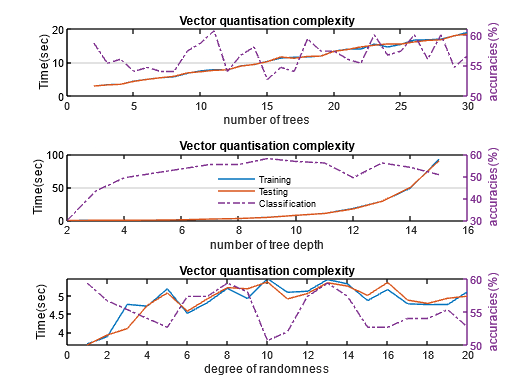

figure
tiledlayout("vertical")

nexttile  %% num tree
num_t=2:30;
acc = acc_by_cb_t * 100; 
plot(num_t, t_tr_by_cb_t, num_t, t_te_by_cb_t);
xlabel('number of trees')
ylabel('Time(sec)') 

title('') 
yyaxis right
ax = gca;
ax.YColor = '[0.4940 0.1840 0.5560]';
hold on
plot(num_t, acc, '-.', "Color", "[0.4940 0.1840 0.5560]");
hold off
% ylim([55 72])
xlabel('number of trees')
ylabel('accuracies(%)') 
% legend({'Training', 'Testing', 'Classification'}, 'Location','northwest')
% legend('boxoff') 
title('Vector quantisation complexity')
% xline(ax, [9 12], ':');
set(gca,"XGrid","off","YGrid","on")
nexttile %% tree depth
d_x = 2:15;
acc = acc_by_cb_d * 100;
plot(d_x, t_tr_by_cb_d, d_x, t_te_by_cb_d);
xlabel('number of tree depth')
ylabel('Time(sec)') 

yyaxis right
ax = gca;
ax.YColor =  '[0.4940 0.1840 0.5560]';
hold on
plot(d_x, acc, '-.', "Color", "[0.4940 0.1840 0.5560]");
hold off
% ylim([55 70])
xlabel('number of tree depth')
ylabel('accuracies(%)') 
legend({'Training', 'Testing', 'Classification'}, 'Location','south')
legend('boxoff') 
title('Vector quantisation complexity')
% xline(ax, [9 12], ':');
set(gca,"XGrid","off","YGrid","on")

nexttile %% degree of randomness
n_splits=1:20;
acc = acc_by_cb_s * 100; 
plot(n_splits, t_tr_by_cb_s, n_splits, t_te_by_cb_s);
xlabel('degree of randomness')
ylabel('Time(sec)') 

yyaxis right
ax = gca;

|================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize | MaxNumSplits | SplitCriteri-| NumVariables-|
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |              | on           | ToSample     |
|================================================================================================================================================================================|
|    1 | Best   |     0.89533 |       1.954 |     0.89533 |     0.89533 |   AdaBoostM2 |           13 |      0.39005 |        29002 |            4 |          gdi |            - |
|    2 | Accept |     0.89533 |      6.8328 |     0.89533 |     0.89533 |          Bag |           12 |  

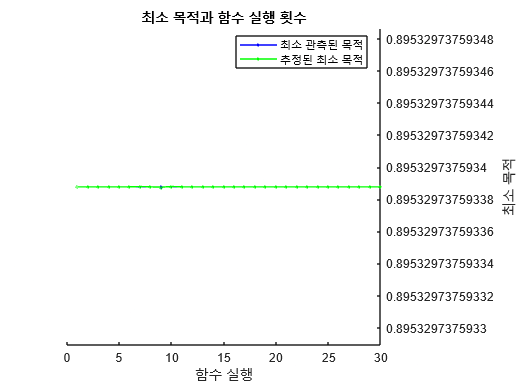

ans =   ClassificationEnsemble
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [1 2 3 4 5 6 7 8 9 10]
                       ScoreTransform: 'none'
                      NumObservations: 420683
    HyperparameterOptimizationResults: [1x1 BayesianOptimization]
                           NumTrained: 0
                               Method: 'AdaBoostM2'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: '요청된 훈련 주기 횟수만큼 완료한 후 정상적으로 종료되었습니다.'
                              FitInfo: [0x1 double]
                   FitInfoDescription: {2x1 cell}


  Properties, Methods


ax.YColor =  '[0.4940 0.1840 0.5560]';
hold on
plot(n_splits, acc, '-.', "Color", "[0.4940 0.1840 0.5560]");
hold off
% ylim([55 70])
% xlabel('num of splits')
ylabel('accuracies(%)') 

% legend({'Training time.', 'Testing time', 'Accuracy'}, 'Location','southeast')
% legend('boxoff') 
title('Vector quantisation complexity')
% xline(ax, [9 12], ':');

- Best pick using below API - 89.53% Bagging, 12 cycles,10 min leaf 7 maximum splits

fitcensemble(d_tr_l(:,1:end-1),d_tr_l(:,end),'OptimizeHyperparameters','all')

b = TreeBagger(50, single(d_tr_l(:,1:end-1)), single(d_tr_l(:,end)),'OOBPredictorImportance','On');
figure
plot(oobError(b))
xlabel('Number of Grown Trees')
ylabel('Out-of-Bag Classification Error')

b = TreeBagger(50, single(d_tr_l(:,1:end-1)), single(d_tr_l(:,end)),'Method', 'classification'); 
predChar1 = B.predict(Ts);  % Predictions is a char though. We want it to be a number.
c = str2double(predChar1);
consistency=sum(c==cl2)/length(cl2);

% bag = bagOfFeatures(d_tr_l,'Verbose',false);
